# Reciprocal Space Tomography on GaV4S8

## Load raw data

load('Cartesian_mesh_Lab.mat','Xc','Yc','Zc'); %meshgrid in [Qx,Qy,Qz] order in nm^-1 units 
load('GVS_intensity_raw.mat','I_cart_cartint'); %Raw intensity data in [Qx,Qy,Qz] order in arbitrary units

## Post processing

Rmax=0.3; %forward scattered intensity
I_cart_cartint(Xc.^2+Yc.^2+Zc.^2<Rmax^2)=NaN; %masking noise within the sphere with r<0.03
I_cart=I_cart_cartint;

## Transform coordinate system from [11-2,111,1-10] to [100,010,001]

T=[1/sqrt(6)*[1;1;-2],-1/sqrt(3)*[1;1;1],1/sqrt(2)*[1;-1;0]];
A=[Xc(:),Yc(:),Zc(:)]*T';
Xt=reshape(A(:,1),size(Xc));
Yt=reshape(A(:,2),size(Yc));
Zt=reshape(A(:,3),size(Zc));

## Show original data without smoothing or symmetrizing

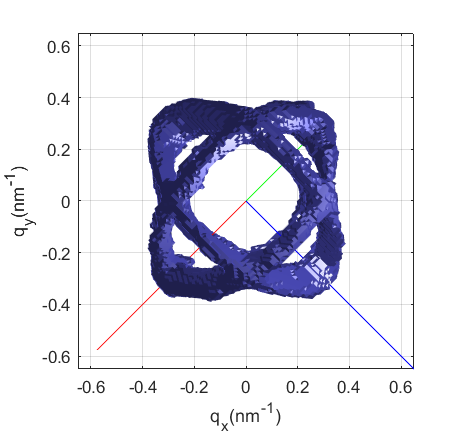

thr=0.15;    %Intensity threshold for visualization : best option: 3.6
alpha=1; % no transparency
col=[0.4,0.4,1]; %blue

figure(2)
wx=9.67;
wy=9.22;
cla
hold on
%Plot_Slicing_Planes;
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha); %Custom function to plot the data with intensities above thr
v2=T'*eye(3);
line([0,v2(1,1)],[0,v2(1,2)],[0,v2(1,3)],'color','green') 
line([0,v2(2,1)],[0,v2(2,2)],[0,v2(2,3)],'color','red') 
line([0,v2(3,1)],[0,v2(3,2)],[0,v2(3,3)],'color','blue') 
%daspect([1 1 1]) 
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.12 11.34 wx wy]);
%view(-162,47); %view1
%view(117,52); %top view
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
xlabel('q_x(nm^{-1})')
ylabel('q_y(nm^{-1})')
zlabel('q_z(nm^{-1})')

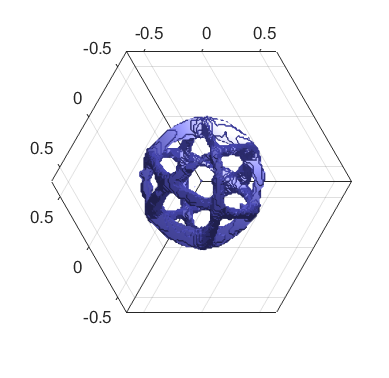


figure(3);
Pos=[5.8208   12.2978    8.2338    8.0010];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
view(1/sqrt(3)*[1,1,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid on

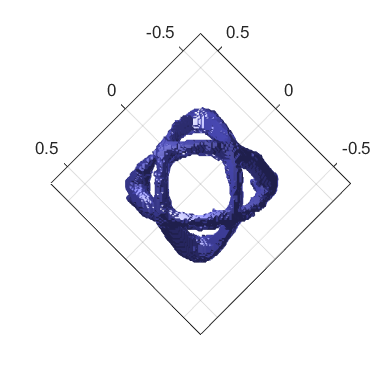


figure(4)
Pos=[14.0547   12.2555    8.2127    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(-54.7,0);
view([0,0,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid on

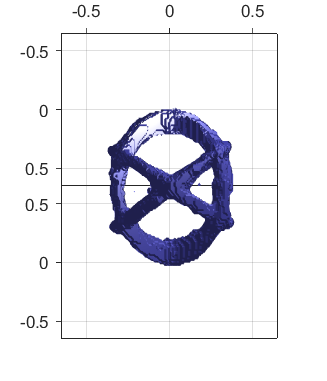


figure(5)
Pos=[22.2038   12.2132    6.9215    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(+35.2,0);
view([1,1,0])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid on

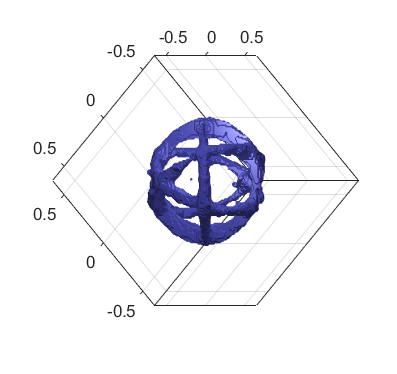


figure(6)
Pos=[29.1888   12.3825    8.4032    7.9163];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
view(1/sqrt(6)*[1,1,2])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
grid on

%}